## BME 3053C 

## Author: Alan Hernandez 

## Group Members: Alan Hernandez, Geraldine E. Pineda Andrade, Kyle Douglas.

## Course: BME 3053C Computer Applications for BME 

## Term: Fall 2022 

## J. Crayton Pruitt Family Department of Biomedical Engineering 

## University of Florida 

## Email: ahernandez17@ufl.edu 

## October, 2022. Last updated: 12/04/2022

# Patch Extraction

Image RGB to grayscale and binary thresholding

I = imread("024.jpg");
I = rgb2gray(I);
avg = sum(sum(I))/(size(I,1)*size(I,2))

avg = 92.6017

binaryim = I > ((avg*2)+10);

For visualization

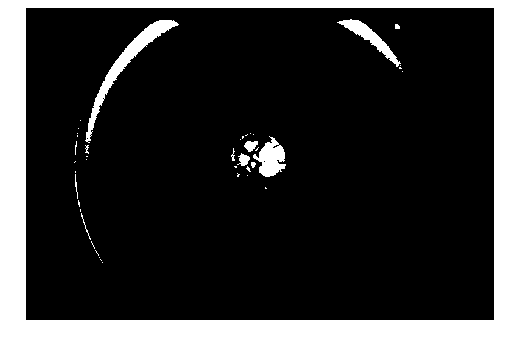

imshow(binaryim)

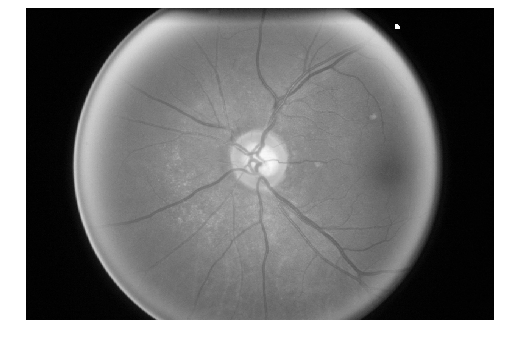

imshow(I)

Filling up holes and clearing the border (1)

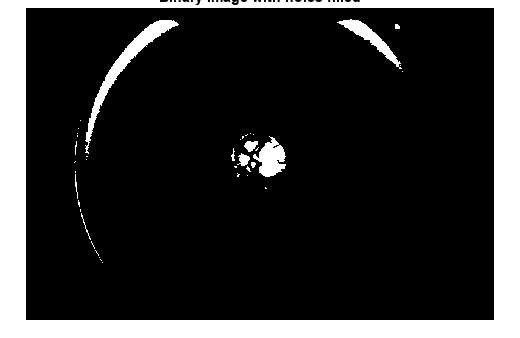

Ifill = imfill(binaryim,"holes");
imshow(Ifill); title("Binary Image with holes filled");

Iclear = imclearborder(Ifill,4);

Previously generated mask from bright circumference edges image

f = load("eye_edge.mat");
F = f.M;

Applying the generated mask to remove bright circumference noise

for i = 1:size(Iclear,1)
    for j = 1:size(Iclear,2)
        if (Iclear(i,j) == 1) && (F(i,j)==1)
            Iclear(i,j)=0;
        end
    end
end

Clearing the border (2)

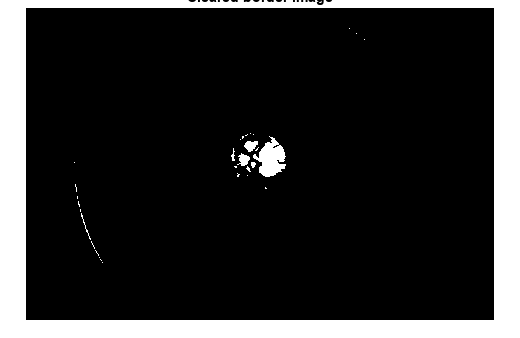

Iclear = imclearborder(Iclear,4);
imshow(Iclear); title('Cleared border image');

Eroding excess

seD = strel('diamond',3);
Ifinal = imerode(Iclear,seD);
mask = imerode(Ifinal,seD);
mask = imerode(mask,seD);

Dilating and Filling up holes, last touches to finished mask

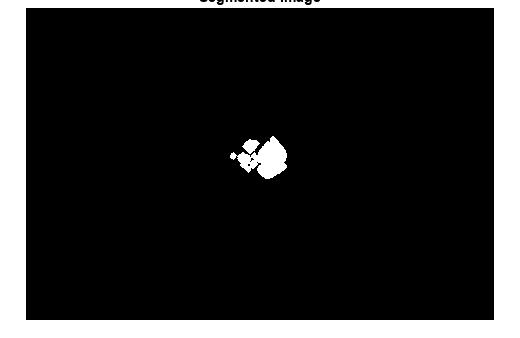

SE = strel("diamond",20);
mask = imdilate(mask,SE);
mask = imfill(mask,26,"holes");
imshow(mask); title("Segmented Image");

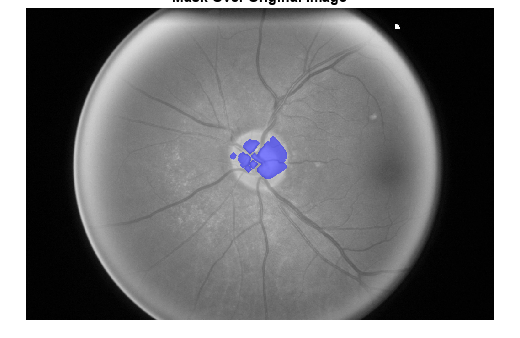

imshow(labeloverlay(I,mask)); title("Mask Over Original Image");

Centroid calculation

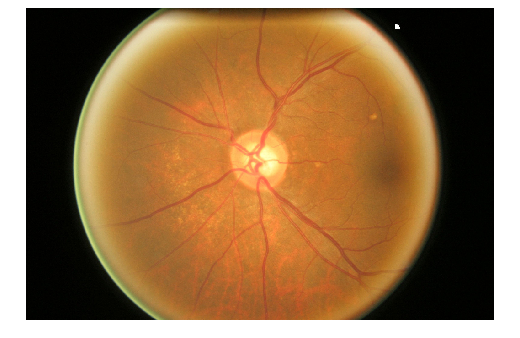

P = imread("024.jpg");
[y, x] = ndgrid(1:size(mask,1), 1:size(mask,2));
centroid = mean([y(logical(mask)), x(logical(mask))]);
centroid = round(centroid);
imshow(P)

Patch extraction (size 600X600) 

Location to begin patch from centroid to top left corner(tlc)

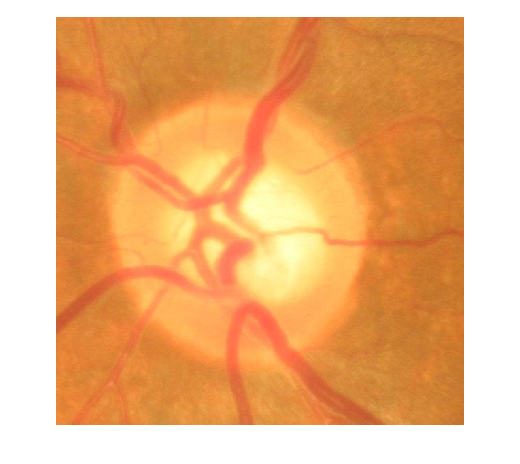

patch = zeros(600,600,3,'uint8');
tlc = [centroid(1)-300 centroid(2)-300];
for i = 1:600
    for j = 1:600
    patch(i,j,1) = P(tlc(1)+i,tlc(2)+j,1);
    patch(i,j,2) = P(tlc(1)+i,tlc(2)+j,2);
    patch(i,j,3) = P(tlc(1)+i,tlc(2)+j,3);
    end
end
imshow(patch)

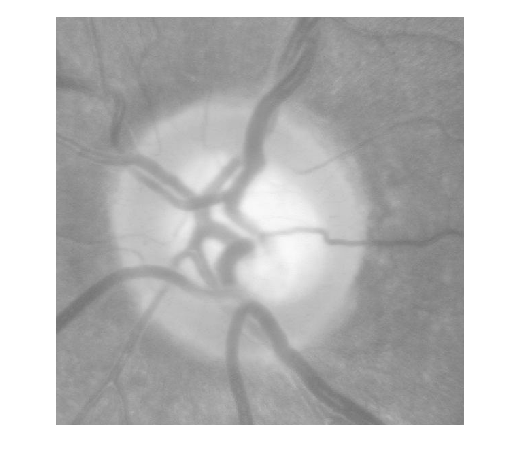

Gpatch=rgb2gray(patch);
imshow(Gpatch)